# Introduction to the @cMosaic (cone mosaic) object

We illustrate basic methods for the cone mosaic class, @cMosaic.  This class creates a cone mosaic arrays and computes the excitations from different optical images (OI).

We illustrate a near fovea @cMosaic object and  compute a number of noisy response instances to a static stimulus with no fixational eye movements, so the computed responses  consist of a single time point.

We also illustrate how to visualize the mosaic and to plot the computed cone excitations.

At the end we illustrate how get all the parameters from the @cMosaic  constructor so you can reliably create the same @cMosaic.  Or, you can create a second @cMosaic with the same parameters and use it to measure the response to a different stimulus.

### See Also:

- t_cMosaicPlots

- t_cMosaicGenerate

- t_cMosaicSingleEyeMovementPath

- t_cMosaicMultipleEyeMovementPaths

- t_cMosaicEccDependentAbsorptionEfficacy

- t_cMosaicBenchMark

- t_cMosaicOffAxis

- t_cMosaicFromConeMosaicHex

## Generate the ring rays stimulus

ieInit;

scene = sceneCreate('rings rays');
scene = sceneSet(scene, 'fov', 1);

## Generate the mosaic

positionDegs = [1 0];
sizeDegs = [1 1];
cm = cMosaic(...
    'sizeDegs', sizeDegs, ...         % SIZE: 1.0 degs (x) 0.5 degs (y)
    'positionDegs', positionDegs, ... % ECC: (0,0)
    'eccVaryingConeBlur', true ...
    );

Recomputing cone aperture zones.
To achieve min cone aperture step of 0.100 (9.684827e-02), we will discretized with 12 steps
min cone aperture diameter = 2.252837 microns


We have a small library of pre-computed mosaics.  You can see which sizes and positions we have by typing 

You can load a stored mosaic and thus avoid the computation this way

cm = mosaicLoad(sizeDegs,positionDegs);

This is the standard human lens model.  It is a good approximation over the central 10 deg (see Visual Encoding:  Principles and Software, in the Circadian Rhythms book, Figure 6).

oi = oiCreate;
oi = oiCompute(scene, oi);

## Visualize of the mosaic and the data

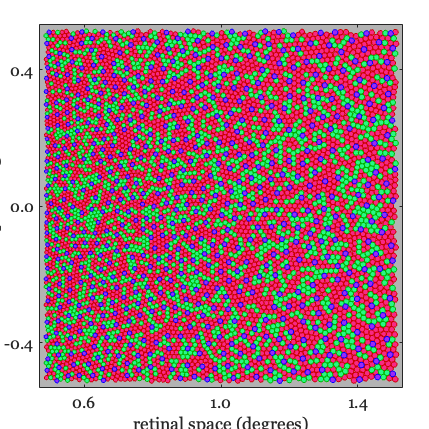

cm.visualize();

## To compute a single noise free instance of the excitations

allE = cm.compute(oi);

Recomputing cone aperture zones.
To achieve min cone aperture step of 1.176 (1.258131e+00), we will discretized with 2 steps
Using 3 blur zones
min cone aperture diameter = 2.252837 microns


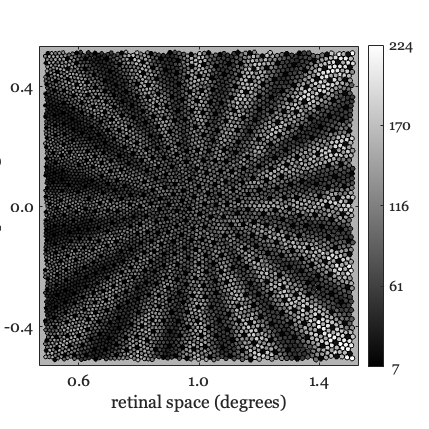


cm.plot('excitations',allE);

## To compute multiple noisy response instances of cone excitation response

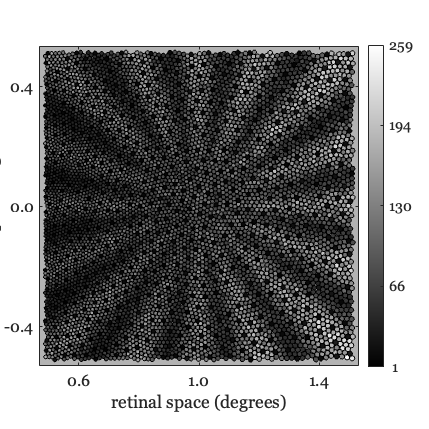

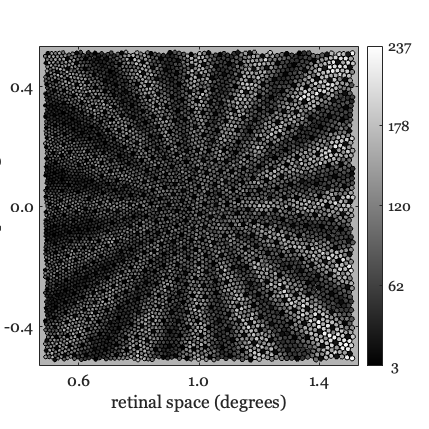

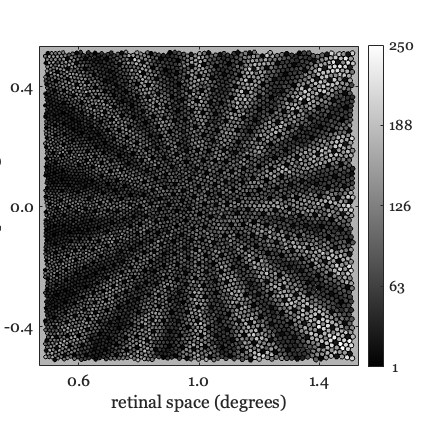

instancesNum = 3;
[~, allNoisyE] = cm.compute(oi, 'nTrials', instancesNum);

for ii=1:instancesNum
    cm.plot('excitations',allNoisyE(ii,1,:));
end

## Make a line @regionOfInterest (ROI) and show it superimposed on the activations

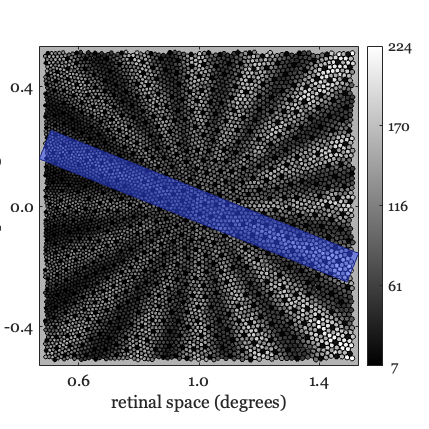

% For help on ROIs, use this
%    regionOfInterest('help');

roiLine = regionOfInterest('shape', 'line', ...
    'from', [.5 0.2], 'to', [1.5,-0.2], ...
    'thickness', 0.1);

% Show the ROI on top of the activations
cm.plot('roi',allE, 'roi',roiLine);

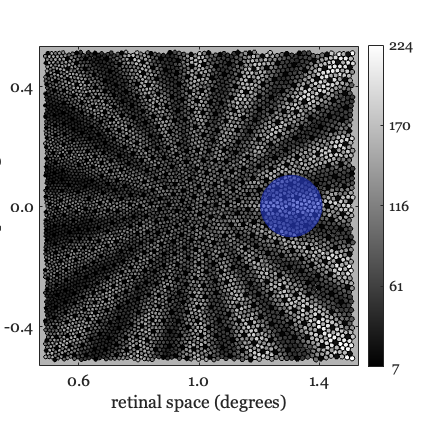


% Now choose a small circular ROI
roiCircle = regionOfInterest('shape','ellipse',...
    'center',[1.3 0],...
    'majorAxisDiameter',0.2,...
    'minorAxisDiameter',0.2);

cm.plot('roi',allE, 'roi',roiCircle);

## Retrieving the excitations within an ROI from all the excitations

roiE = cm.excitations('roi',roiCircle,'all excitations',allE);
mean(roiE)

ans = 92.2961


roiLE = cm.excitations('roi',roiCircle,...
    'all excitations',allE, ...
    'cone type','L');
mean(roiLE)

ans = 108.1477


% Fewer and lower excitations of S-cones.
[roiSE, roiSIdx] = cm.excitations('roi',roiCircle,...
    'all excitations',allE, ...
    'cone type','S');
mean(roiSE)

ans = 14.5355

## Get the excitations and visualize in one call

[roiE, roiIdx, allE] = cm.excitations('roi',roiCircle,'visualize',true,'all excitations',allE);

## Visualize responses - NC code. Thinking what to do

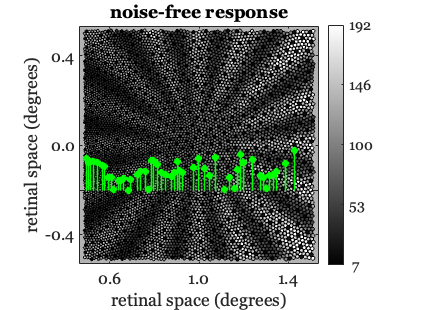

hFig = ieNewGraphWin;
activationRange = prctile(allNoisyE(:), [1 99]);

% Noise-free response
cm.visualize('figureHandle', hFig, 'axesHandle', gca, ...
    'activation', allE, ...
    'activationRange', activationRange, ...
    'verticalActivationSliceEccentricity', -0.2, ...
    'verticalActivationColorBar', true, ...
    'plotTitle',  'noise-free response');

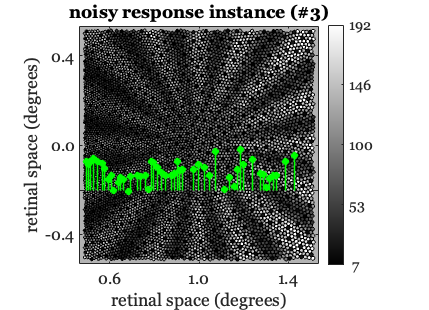


% Loop over noisy response instances
hFig = ieNewGraphWin;

for k = 1:instancesNum
    cm.visualize('figureHandle', hFig, 'axesHandle', gca, ...
        'activation', allNoisyE(k,:,:), ...
        'activationRange', activationRange, ...
        'verticalActivationSliceEccentricity', -0.2, ...
        'verticalActivationColorBar', true, ...
        'plotTitle', sprintf('noisy response instance (#%d)', k));
    pause(1);
end

## Making a reproducible cMosaic

For some calculations you would like to re-generate a repeatable, rather than random, cone mosaic.  You can use the randomSeed slot for that.

% Here is the first mosaic.  The second argument is the list of
% parameters used to create the mosaic.
[cm1, cm1P] = cMosaic(...
  'sizeDegs', [1.0 1.0], ...% SIZE: 1.0 degs (x) 0.5 degs (y)
  'positionDegs', [1 0], ...% ECC: (0,0)
  'eccVaryingConeBlur', true, ...
  'randomSeed', 12 ...
  );

Recomputing cone aperture zones.
To achieve min cone aperture step of 0.100 (9.684827e-02), we will discretized with 12 steps
min cone aperture diameter = 2.252837 microns



% Here is the second one, same random seed, so it matches
[cm2, cm2P] = cMosaic(...
  'sizeDegs', [1.0 1.0], ...% SIZE: 1.0 degs (x) 0.5 degs (y)
  'positionDegs', [1 0], ...% ECC: (0,0)
  'eccVaryingConeBlur', true, ...
  'randomSeed', 12 ...
  );

Recomputing cone aperture zones.
To achieve min cone aperture step of 0.100 (9.684827e-02), we will discretized with 12 steps
min cone aperture diameter = 2.252837 microns



% The parameters are equal because, well, we sent in the same
% parameters.
isequal(cm1P,cm2P)

ans = logical
   0


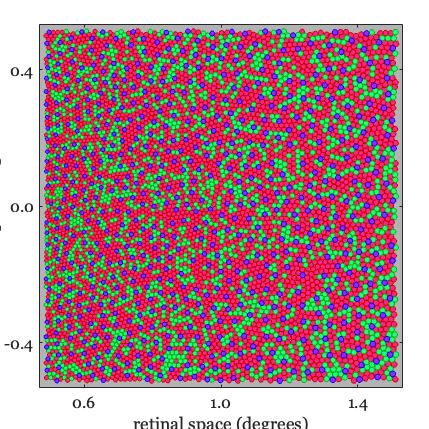


% You can see the two mosaics are the same this way:
cm1.visualize;

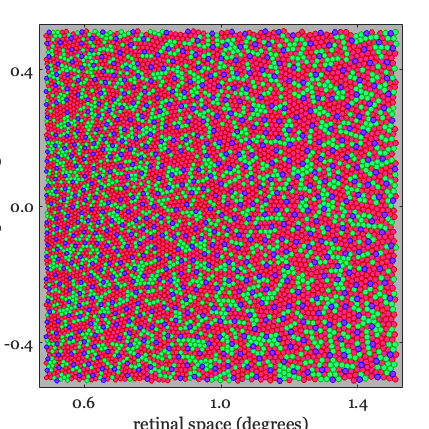

cm2.visualize;

## To create the mosaic from specifying the parameters, you can do this

Sometimes you just want to control all the parameters.  So using the parameter list from above, we can create a mosaic this way.

[cm3, cm3P] = cMosaic(cm1P);

Recomputing cone aperture zones.
To achieve min cone aperture step of 0.100 (9.684827e-02), we will discretized with 12 steps
min cone aperture diameter = 2.252837 microns



% Check that the parameters remained equal.
isequal(cm1P,cm3P)

ans = logical
   0


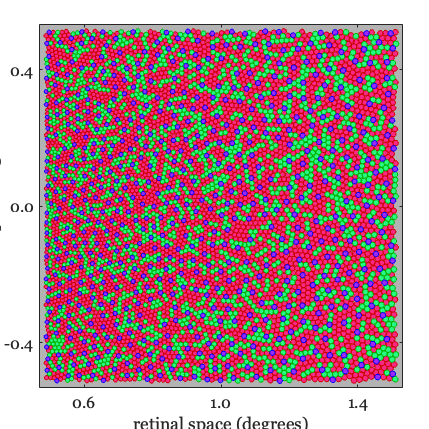


% Have a look to see they are equal.
cm3.visualize;

## You can change a parameter this way and see that it is different.

cm3P.randomSeed = 11;
cm4 = cMosaic(cm3P);

Recomputing cone aperture zones.
To achieve min cone aperture step of 0.100 (9.684827e-02), we will discretized with 12 steps
min cone aperture diameter = 2.252837 microns


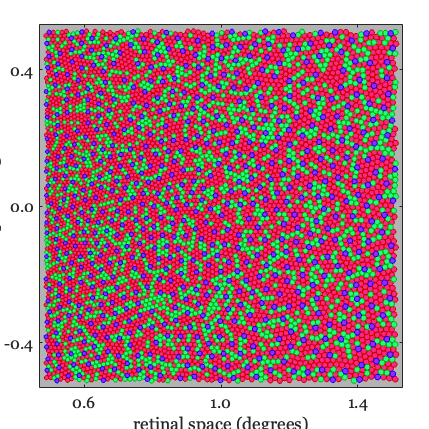

cm4.visualize;

## You can also get the default set of parameters this way

% This creates a random mosaic.
cmP = cMosaicParams;
[cm, cmP1] = cMosaic(cmP);

min cone aperture diameter = 1.694712 microns


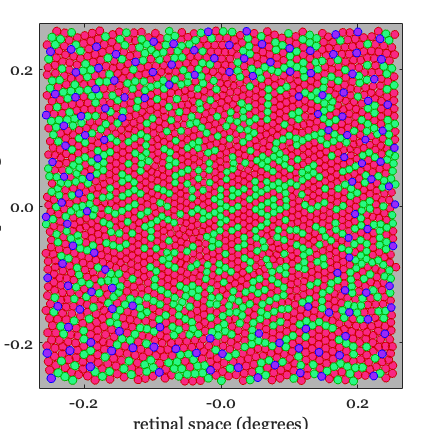

cm.visualize;


% The random seed is returned - if you use the parameters again, you
% will get the same mosaic.
cmP1.randomSeed

ans = 304231

## END